# **TASK 1)**

# Part a)

clear; % Clear workspace

N = 100; % Ex. number of samples

theta_true = [0; 0]; % True parameters as per Appendix A
sigma2 = 1; % Variance of the errors -> normally distr. with mean zero

% dataset
X = [ones(N, 1), (1 + (-1).^(1:N))']; % Design matrix
e = randn(N, 1) * sqrt(sigma2); % Errors
y = e; % Outputs as per Appendix A, y_i = e_i since theta_true = [0; 0]

% Estimating parameters using the LinRegress function
m = LinRegress(X, y);

% Est. variance - 1ST param
estimated_variance = m.variance(1, 1);

% Theoretical variance (Appendix A)
theoretical_variance = sigma2 / N; 

fprintf('True parameters: %f\n', theta_true);

True parameters: 0.000000
True parameters: 0.000000


fprintf('Estimated parameter: %f\n', m.theta);

Estimated parameter: -0.445099
Estimated parameter: 0.286007


fprintf('Estimated variance for the first parameter: %f\n', estimated_variance);

Estimated variance for the first parameter: 0.017394


fprintf('Theoretical variance for the first parameter: %f\n', theoretical_variance);

Theoretical variance for the first parameter: 0.010000


# Part b)                                                                             *****Testing The Function*****

% testing evalmodel and linregress
X_example = [ones(10, 1), (1:10)']; % 10 samples with linear trend -> has intercept
theta_example = [1; 2]; % true params   
y_example = X_example * theta_example + randn(10, 1) * 0.5; % Generating example outputs with some noise

% LinRegress to estimate the model parameters from the example data
model_estimated = LinRegress(X_example, y_example);

% Using/testing evalModel to predict outputs based on the estimated model and a new set of regressors
X_new = [ones(5, 1), (11:15)']; % New regressor values for prediction
y_pred = evalModel(model_estimated, X_new);

disp('Predicted outputs:');

Predicted outputs:


disp(y_pred);

   23.3692
   25.4175
   27.4659
   29.5142
   31.5625



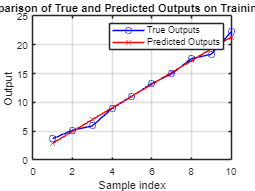


% Plotting the true and predicted outputs for the example data
figure;
plot(1:10, y_example, 'bo-', 1:10, evalModel(model_estimated, X_example), 'rx-');
xlabel('Sample index');
ylabel('Output');
legend('True Outputs', 'Predicted Outputs');
title('Comparison of True and Predicted Outputs on Training Data');
grid on;

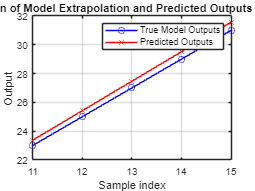


% Plotting the true model continuation and predicted outputs for the new data
y_true_new = X_new * theta_example; % True outputs for the new data based on the true model
figure;
plot(11:15, y_true_new, 'bo-', 11:15, y_pred, 'rx-');
xlabel('Sample index');
ylabel('Output');
legend('True Model Outputs', 'Predicted Outputs');
title('Comparison of Model Extrapolation and Predicted Outputs on New Data');
grid on;

# Part c)                                                                              *****Testing The Function*****

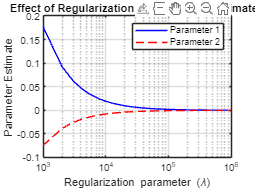

%impact of regularization on parameter estimation in LR.  Lambda acts as a penalty term 
% that controls the complexity of the model by shrinking the parameter estimates towards zero to prevent overfitting
clear; 

% range for the regularization parameter lambda
lambda_values = 0:1000:1e6; % From 0 -> 10^6
num_lambdas = length(lambda_values);

% Initialize arrays to store the estimates
theta_estimates = zeros(num_lambdas, 2); % for two parameters in the model

% true parameters and generate dataset
N = 100;
X = [ones(N, 1), randn(N, 1)]; % Design matrix with intercept
theta_true = [2; -1]; % True params
y = X * theta_true + randn(N, 1) * 0.1; % Generating outputs with noise

% Loop over lambda values and estim params
for i = 1:num_lambdas
    lambda = lambda_values(i);
    m = LinRegressRegul(X, y, lambda);
    theta_estimates(i, :) = m.theta;
end

% Plotting
figure;
semilogx(lambda_values, theta_estimates(:, 1), 'b-', 'DisplayName', 'Parameter 1');
hold on;
semilogx(lambda_values, theta_estimates(:, 2), 'r--', 'DisplayName', 'Parameter 2');
xlabel('Regularization parameter (\lambda)');
ylabel('Parameter Estimate');
legend('show');
title('Effect of Regularization on Parameter Estimates');
grid on;

# Part d)                                                                             *****Testing The Function*****

% original regressors and the degree of the polynomial
x = [2 3; 4 5];
n = 3;

% new regressor matrix for polynomial fitting
[x2,allpot] = poly_x2(x,n);

disp(x2);

     1     2     3     4     6     9     8    12    18    27
     1     4     5    16    20    25    64    80   100   125



# Part e)                                                                             *****Testing The Function*****

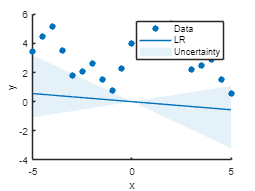

clear;
% Estimation data
x=(-5:0.5:5)';

% linear function plus noise
y=3+1.5*sin(x)+real((-1).^x);

m=LinRegress(x,y);
poly = polyfit(x,y,0,3);
knn = knnRegress(x,y,3);

x2=(-5:0.1:5)';

figure;
plotModel(x,y,m);

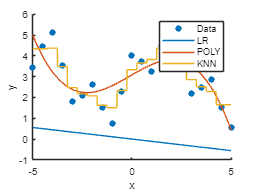


figure;
plotModel(x,y,m,poly,knn);

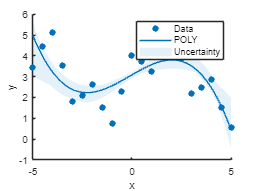


figure;
plotModel(x,y,poly);

# **TASK 2)**

# *****Testing The Function*****

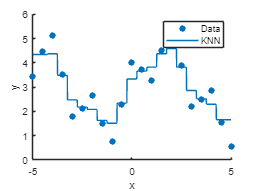

clear;
% Estim data
x = (-5:0.5:5)';
y = 3 + 1.5 * sin(x) + real((-1).^x);

% KNN regr with k=3 & k=5
knn3 = knnRegress(x, y, 3);
knn5 = knnRegress(x, y, 5);
LR = LinRegress(x,y);

figure;
plotModel(x, y, knn3);

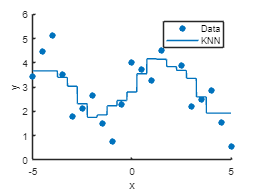

figure;
plotModel(x, y, knn5);

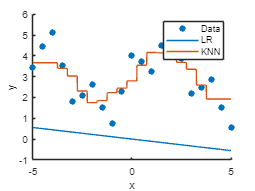

figure;
plotModel(x, y, LR, knn5);

# **Functions Developed:**

function m = LinRegress(x,y)
%used to estimate the model parameters from the design matrix X and output vector y
    [Ny,ny] = size(y);
    [Nx,nx] = size(x);
    m.model = 'LR'; % linear regr.model
    
    if Nx == Ny % Test that the number of data is the same in x and y ->so each pred has a correspo. value
        
        m.theta = (x'*x)\(x'*y); % LS estimation of regress coeffs
           
        if ny == 1 % calculate uncertainty only in the case that there is one output
            %If the model has only one output, calculate the residuals and 
            % use these to estimate the variance of the error term

            % Estimating the variance of the error term
            residuals = y - x * m.theta; %error terms for each observation, indicating how much the model's 
                                         % prediction deviates from the actual observed value
                                         
            sigma2 = (residuals' * residuals) / (Ny - nx); % according to 4.13 the residuals should be
                                        
            % variance of the parameters
            m.variance = sigma2 * inv(x' * x); % variance of theta_hat
            
        else
           m.variance = 'None';
        end
    else
        m.theta = NaN;
        m.model = 'None';
        m.variance = 'None';
        disp('Dimension mismatch for output and regressor.')
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function y_pred = evalModel(m, X)
    if strcmp(m.model, 'LR') || strcmp(m.model, 'POLY') % Linear or Polynomial models

        y_pred = X * m.theta(:);

    elseif strcmp(m.model, 'knn') % KNN model
        y_pred = zeros(size(X, 1), 1); % Initializing the output

        for i = 1:size(X, 1)
            % For each new input, calculate distances from training data, 
            % find the knn, and average their outputs to make a prediction
            distances = sqrt(sum(bsxfun(@minus, m.x, X(i)).^2, 2));
            [~, sortedIndices] = sort(distances);
            closestIndices = sortedIndices(1:m.k);
            y_pred(i) = mean(m.y(closestIndices));
        end

    else
        error('Unknown model type');
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function m = LinRegressRegul(x, y, lambda)
%extending linregress to prevent overfitting
%by appending scaled identity matrices and zero vectors, respectively 
% This effectively adds a regularization term (λθ^2) to the least squares loss function

    % Appending extra rows to x and y for regularization
    x2 = [x; sqrt(lambda)*eye(size(x,2))];
    y2 = [y; zeros(size(x,2), 1)];
    
    % LinRegress function on the updated x2 and y2
    m = LinRegress(x2, y2);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [x2, allpot] = poly_x2(x, n)
% expanding the feature space to include polynomial terms, 
% which allows the linear model to fit more complex patterns
    [Nx, nx] = size(x);

    % Generating all possible combinations of exponents for monomials
    if nx == 1
        % If only one regressor simply generating the powers of it
        allpot = (0:n)';
    else
        % combinations for multiple regressors
        allpot = [];
        for total_degree = 0:n
            % Generatin & appending combinations for the current total degree
            allpot = [allpot; flipud(generateCombinations(nx, total_degree))];
        end
    end
    
    nmon = size(allpot, 1); % No. of monomials is the number of rows in allpot
    
    % Preparing empty matrix for the extended regressor matrix
    x2 = ones(Nx, nmon);
    
    % Fill in the x2 matrix
    for ii = 1:nmon
        % Calculating each monomial using one row of allpot and x
        for var_idx = 1:nx
            x2(:, ii) = x2(:, ii) .* (x(:, var_idx) .^ allpot(ii, var_idx));
        end
    end
end

function combinations = generateCombinations(num_vars, total_degree)
%  a recursive helper function for poly_x2 to generate all combinations of exponents 
% for a given total degree across multiple variables.
    % all combinations of exponents for num_vars summing to total_degree
    if num_vars == 1
        combinations = total_degree;
    else
        combinations = [];
        for i = 0:total_degree
            % Recursively generating combinations for one less variable
            sub_combinations = generateCombinations(num_vars - 1, total_degree - i);
            % Pre-apending the current exponent to each combination
            combinations = [combinations; [i * ones(size(sub_combinations, 1), 1), sub_combinations]];
        end
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function m = polyfit(x, y, lambda, n)
    % extended regressor matrix -> lambda to ->reg. param to control degree
    % of shrinkage
    [x2, allpot] = poly_x2(x, n);

    % regularized linear regression using the extended matrix
    m = LinRegressRegul(x2, y, lambda);
    m.n = n;
    m.model = 'POLY'; % polynomial regr.model
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function plotModel(x, y, varargin)

    scatter(x, y, 'filled', 'DisplayName', 'Data'); % for data points
    hold on;
    
    % Colors for plotting each model
    colors = lines(max(length(varargin), 1));

    %  for smooth plots
    x2 = linspace(min(x), max(x), 1000)';  % could have been x2=(-5:0.1:5)';  
                                           % according to Test_plotModel
                                           

    for i = 1:length(varargin) %iterating over each model
        m = varargin{i};

        % Check-point for the model type
        if strcmp(m.model, 'knn')
            % KNN model
            y_pred = evalModel(m, x2); % Directly use x2 for KNN
            plot(x2, y_pred, 'Color', colors(i,:), 'DisplayName', 'KNN');
        elseif strcmp(m.model, 'POLY')
            % Polynomial model
            X_design = poly_x2(x2, m.n);
            y_pred = evalModel(m, X_design);
            plot(x2, y_pred, 'Color', colors(i,:), 'DisplayName', 'POLY');
        else
            % Linear model
            X_design = [ones(size(x2, 1), 1), x2];
            y_pred = evalModel(m, X_design);
            % excluding the intercept (1st.col) 
            [yr, yc] = size(y_pred);
            if yc >= 2
                y_pred = y_pred(:,2:end);
                plot(x2, y_pred, 'Color', colors(i,:), 'DisplayName', 'LR');
            else
                plot(x2, y_pred, 'Color', colors(i,:), 'DisplayName', 'LR');
            end

        end


        % uncertainty for a single model with variance information
        if length(varargin) == 1 && isfield(varargin{1}, 'variance') && ...
                size(varargin{1}.variance, 1) == size(varargin{1}.variance, 2)
   
            m = varargin{1};
    
            % Generating the design matrix depending on the model type
            if strcmp(m.model, 'LR')
                X_design = [ones(size(x2, 1), 1), x2];  % Adding intercept for linear regression
            elseif strcmp(m.model, 'POLY')
                X_design = poly_x2(x2, m.n);  % includes the intercept in the design
            end
%%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%%  
%%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%%  
            num_samples = 10;  %%%%%%%%%%%%%% ADJUST sampling size %%%%%%%%%%%%%%
%%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%%  
%%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%%  

            y_sims = zeros(length(x2), num_samples);

            % Generatin outputs for each sample using Monte Carlo simu.
            for i = 1:num_samples
                % Sample from the parameter distribution
                theta_sample = mvnrnd(m.theta, m.variance); % Monte Carlo simulations rely on repeated random sampling to approximate a statistical measurement. 
%mvnrnd function is used to draw random samples from a multivariate normal distribution defined 
% by the estimated parameters (theta) and their variance matrix. used to generate all possible 
% terms up to the specified polynomial degree   

                % Since random numbers are involved, the output can vary with each run 
                % unless the random number generator seed is fixed.
                % in case consistent plots are needed we can use: 
                % rng(123); % Sets the seed of the random number generator for reproducibility
                
        
                % checkin the model with the sampled params
                if strcmp(m.model, 'POLY')
                    y_sims(:, i) = evalModel(struct('theta', theta_sample, 'model', m.model), X_design);
                else
                    % x2 can be passed directly
                    y_sims(:, i) = evalModel(struct('theta', theta_sample, 'model', m.model), x2);
                end
            end

            % the 2.5th and 97.5th percentiles -> to achieve a 95% confidence  
            y_lower = prctile(y_sims, 2.5, 2);
            y_upper = prctile(y_sims, 97.5, 2);
%computes the 2.5th percentile (lower bound) of the predicted values for each point in x2 
% across all simulations, and prctile(y_sims, 97.5, 2) computes the 97.5th percentile (upper bound). 
% The second argument in prctile specifies the dimension along which the percentiles are calculated, 
%ensuring the function evaluates across the simulations rather than across the different points in x2.
            % Plotting 
            fill([x2; flipud(x2)], [y_upper; flipud(y_lower)], ...
                colors(1,:), 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', 'Uncertainty');
        end

        
    end

    xlabel('x');
    ylabel('y');
    legend show;
    hold off;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function m = knnRegress(x, y, k)
    % KNN model
    m.x = x;
    m.y = y;
    m.k = k;
    m.model = 'knn'; 
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%